
% Số file dữ liệu cần xử lý
NUM_FILES = 10;

if ~exist('Fs', 'var'),     Fs = 2000000; end % Tần số lấy mẫu (Hz)
if ~exist('N_FFT', 'var'), N_FFT = 4096; end % Số điểm FFT

% Mảng map các bins tần số mục tiêu từ STM32
bins_noDC = [2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 13, 14, 16, 18, 20];

% Tính toán tần số vật lý tương ứng với từng bin: f = bin * Fs / N_FFT
f_target = bins_noDC * (Fs / N_FFT);

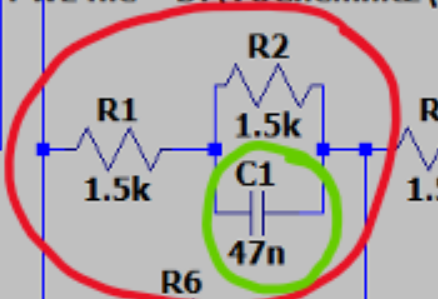

%% ========================================================================
% THÔNG SỐ LÝ THUYẾT (Cole-Cole)
% ========================================================================
Rs_theory = 1500;
Rp_theory = 1500;
Cp_theory = 47e-9;
f_c       = 1 / (2 * pi * Rp_theory * Cp_theory);

% Đường cong lý thuyết liên tục
f_cont   = logspace(log10(10), log10(Fs/2), 3000);
w_cont   = 2 * pi * f_cont;
Z_cont   = Rs_theory + Rp_theory ./ (1 + 1j * w_cont * Rp_theory * Cp_theory);

% Tính toán trở kháng lý thuyết tại các bin đo
w_target  = 2 * pi * f_target;
Z_th_bins = Rs_theory + Rp_theory ./ (1 + 1j * w_target * Rp_theory * Cp_theory);

Re_th  = real(Z_th_bins);
Im_th  = imag(Z_th_bins);
Mag_th = abs(Z_th_bins);
Ph_th  = angle(Z_th_bins) * 180/pi;

fprintf('\n=== Theoretical DUT ===\n');


=== Theoretical DUT ===


fprintf('Rs = %.0f Ohm  |  Rp = %.0f Ohm  |  Cp = %.1f nF\n', Rs_theory, Rp_theory, Cp_theory*1e9);

Rs = 1500 Ohm  |  Rp = 1500 Ohm  |  Cp = 47.0 nF


fprintf('f_characteristic = %.2f kHz\n', f_c/1e3);

f_characteristic = 2.26 kHz


fprintf('Z(f->0)   = Rs+Rp = %.0f Ohm\n', Rs_theory+Rp_theory);

Z(f->0)   = Rs+Rp = 3000 Ohm


fprintf('Z(f->inf) = Rs    = %.0f Ohm\n', Rs_theory);

Z(f->inf) = Rs    = 1500 Ohm


# ***Import Data and Calculate magnitude & phase error***

%% ========================================================================
% IMPORT VÀ XỬ LÝ 10 FILE DỮ LIỆU
% ========================================================================
% Khởi tạo mảng lưu kết quả cho tất cả các file
all_Mag_meas = zeros(NUM_FILES, length(bins_noDC));
all_Ph_meas  = zeros(NUM_FILES, length(bins_noDC));
all_Re_meas  = zeros(NUM_FILES, length(bins_noDC));
all_Im_meas  = zeros(NUM_FILES, length(bins_noDC));

colors = lines(NUM_FILES); % Tạo bảng màu phân biệt cho từng file

fprintf('\n=== Đang import dữ liệu từ %d files ===\n', NUM_FILES);


=== Đang import dữ liệu từ 10 files ===



for file_idx = 1:NUM_FILES
    filepath = sprintf('DATA/%d.txt', file_idx);
    
    % Kiểm tra file có tồn tại không
    if ~isfile(filepath)
        warning('Không tìm thấy file: %s — Bỏ qua.', filepath);
        continue;
    end
    
    % Đọc file: định dạng mỗi dòng là "cnt, Mag, Phase, accMag, accPhase"
    fid = fopen(filepath, 'r');
    raw = textscan(fid, '%f %f %f %f %f', 'Delimiter', ',', 'CollectOutput', true);
    fclose(fid);
    
    stm32_data = raw{1};
    
    % Kiểm tra số dòng đủ cho bins không
    if size(stm32_data, 1) < length(bins_noDC)
        warning('File %s chỉ có %d dòng, cần ít nhất %d. Bỏ qua.', ...
            filepath, size(stm32_data, 1), length(bins_noDC));
        continue;
    end
    
    % Trích xuất đúng số hàng ứng với bins_noDC (lấy các hàng 1..numel(bins_noDC))
    Mag_raw = stm32_data(1:length(bins_noDC), 2)';
    Ph_raw  = stm32_data(1:length(bins_noDC), 3)';
    
    % 1. Lấy dữ liệu pha thô từ STM32
    Ph_norm = Ph_raw;
    
    % 2. Chuẩn hóa pha (Unwrap/Shift) bằng cách trừ đi 180 độ 
    % (để đưa từ vùng +165° về vùng góc âm chuẩn -15° của hệ RC)
    Ph_norm = Ph_norm - 180;
    
    % 3. Đưa góc về khoảng [-180, 180] nếu cần thiết
    Ph_norm(Ph_norm < -180) = Ph_norm(Ph_norm < -180) + 360;
    Ph_norm(Ph_norm > 180)  = Ph_norm(Ph_norm > 180) - 360;
    
    % 4. Lưu kết quả đồng bộ cho cả Bode Phase và Nyquist
    all_Mag_meas(file_idx, :) = Mag_raw;
    all_Ph_meas(file_idx, :)  = Ph_norm; % Bode Phase sẽ tự động đúng
    
    % Phần thực và phần ảo tính từ Ph_norm mới cũng sẽ tự động chuẩn
    all_Re_meas(file_idx, :)  = Mag_raw .* cosd(Ph_norm);
    all_Im_meas(file_idx, :)  = Mag_raw .* sind(Ph_norm);
    
    fprintf('  [OK] File %d: %s  (%d bins)\n', file_idx, filepath, length(bins_noDC));
end

  [OK] File 1: DATA/1.txt  (15 bins)
  [OK] File 2: DATA/2.txt  (15 bins)
  [OK] File 3: DATA/3.txt  (15 bins)
  [OK] File 4: DATA/4.txt  (15 bins)
  [OK] File 5: DATA/5.txt  (15 bins)
  [OK] File 6: DATA/6.txt  (15 bins)
  [OK] File 7: DATA/7.txt  (15 bins)
  [OK] File 8: DATA/8.txt  (15 bins)
  [OK] File 9: DATA/9.txt  (15 bins)
  [OK] File 10: DATA/10.txt  (15 bins)



%% ========================================================================
% PHÂN TÍCH SAI SỐ CHO TỪNG FILE
% ========================================================================
fprintf('\n%s\n', repmat('=',1,80));

fprintf('=== PER-FILE IMPEDANCE ERROR SUMMARY ===\n');

=== PER-FILE IMPEDANCE ERROR SUMMARY ===


fprintf('%s\n', repmat('=',1,80));


for file_idx = 1:NUM_FILES
    if all(all_Mag_meas(file_idx,:) == 0)
        continue; % Bỏ qua file bị lỗi khi đọc
    end
    
    err_mag_pct = (all_Mag_meas(file_idx,:) - Mag_th) ./ Mag_th * 100;
    err_ph_deg  = all_Ph_meas(file_idx,:) - Ph_th;
    
    fprintf('\n--- File %d ---\n', file_idx);
    fprintf('%-6s %-10s %-12s %-12s %-14s %-12s\n', ...
        'Bin','Freq(Hz)','|Z|_theory','|Z|_meas','Err_mag(%)','Err_ph(deg)');
    for k = 1:length(bins_noDC)
        fprintf('%-6d %-10.1f %-12.2f %-12.2f %-14.4f %-12.4f\n', ...
            bins_noDC(k), f_target(k), Mag_th(k), all_Mag_meas(file_idx,k), ...
            err_mag_pct(k), err_ph_deg(k));
    end
    fprintf('  Mean |err_mag| = %.4f %%\n', mean(abs(err_mag_pct)));
    fprintf('  Mean |err_ph|  = %.4f deg\n', mean(abs(err_ph_deg)));
end


--- File 1 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2760.22      -2.0186        -2.6011     
3      1464.8     2645.76      2502.75      -5.4053        -2.6025     
4      1953.1     2471.93      2323.11      -6.0202        -1.3933     
5      2441.4     2315.44      2175.13      -6.0597        -0.7603     
6      2929.7     2182.83      2042.79      -6.4158        -0.0101     
7      3418.0     2073.70      1942.18      -6.3420        0.2394      
8      3906.2     1984.95      1872.50      -5.6650        1.1951      
9      4394.5     1912.95      1813.41      -5.2036        1.1658      
10     4882.8     1854.39      1762.27      -4.9675        1.4229      
11     5371.1     1806.49      1724.34      -4.5478        1.4096      
13     6347.7     1734.33      1674.26      -3.4638        1.5772      
14     6835.9     1706.98      1652.63      -3.1837        1.7307      
16     7812.5     1664.39      1617.60      -2.8112        1.7354      
18     8789.1     1633.33      1596.20      -2.2734        1.531

  Mean |err_mag| = 4.4267 %


  Mean |err_ph|  = 1.3804 deg



--- File 2 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2765.50      -1.8313        -2.4061     
3      1464.8     2645.76      2496.60      -5.6376        -2.5035     
4      1953.1     2471.93      2328.93      -5.7849        -1.3853     
5      2441.4     2315.44      2175.82      -6.0300        -0.8173     
6      2929.7     2182.83      2043.61      -6.3782        -0.0781     
7      3418.0     2073.70      1946.14      -6.1513        0.4364      
8      3906.2     1984.95      1870.72      -5.7545        0.9721      
9      4394.5     1912.95      1810.82      -5.3392        1.1298      
10     4882.8     1854.39      1770.38      -4.5302        1.4589      
11     5371.1     1806.49      1729.59      -4.2570        1.2546      
13     6347.7     1734.33      1673.89      -3.4852        1.6502      
14     6835.9     1706.98      1655.97      -2.9881        1.6297      
16     7812.5     1664.39      1612.93      -3.0914        1.5954      
18     8789.1     1633.33      1597.97      -2.1648        1.394

  Mean |err_mag| = 4.3719 %


  Mean |err_ph|  = 1.3367 deg



--- File 3 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2762.91      -1.9233        -2.3741     
3      1464.8     2645.76      2499.99      -5.5095        -2.5505     
4      1953.1     2471.93      2324.90      -5.9477        -1.4323     
5      2441.4     2315.44      2177.38      -5.9623        -0.6643     
6      2929.7     2182.83      2045.85      -6.2757        -0.0761     
7      3418.0     2073.70      1945.13      -6.1998        0.3294      
8      3906.2     1984.95      1871.89      -5.6957        0.9371      
9      4394.5     1912.95      1813.89      -5.1784        1.3398      
10     4882.8     1854.39      1767.46      -4.6880        1.4129      
11     5371.1     1806.49      1723.67      -4.5848        1.2626      
13     6347.7     1734.33      1674.93      -3.4252        1.7182      
14     6835.9     1706.98      1651.45      -3.2530        1.7007      
16     7812.5     1664.39      1620.66      -2.6273        1.6634      
18     8789.1     1633.33      1595.11      -2.3402        1.666

  Mean |err_mag| = 4.3767 %


  Mean |err_ph|  = 1.3620 deg



--- File 4 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2764.50      -1.8667        -2.3701     
3      1464.8     2645.76      2495.71      -5.6714        -2.5655     
4      1953.1     2471.93      2328.63      -5.7971        -1.4653     
5      2441.4     2315.44      2177.83      -5.9431        -0.6963     
6      2929.7     2182.83      2047.91      -6.1813        -0.0071     
7      3418.0     2073.70      1948.95      -6.0157        -0.3606     
8      3906.2     1984.95      1874.44      -5.5670        0.9961      
9      4394.5     1912.95      1812.84      -5.2332        1.1888      
10     4882.8     1854.39      1768.70      -4.6207        1.3589      
11     5371.1     1806.49      1726.17      -4.4461        1.4496      
13     6347.7     1734.33      1669.38      -3.7448        1.4812      
14     6835.9     1706.98      1652.21      -3.2085        1.6747      
16     7812.5     1664.39      1618.23      -2.7733        1.5964      
18     8789.1     1633.33      1598.25      -2.1479        1.620

  Mean |err_mag| = 4.3522 %


  Mean |err_ph|  = 1.3402 deg



--- File 5 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2756.94      -2.1352        -2.3601     
3      1464.8     2645.76      2502.69      -5.4075        -2.5165     
4      1953.1     2471.93      2330.71      -5.7129        -1.4243     
5      2441.4     2315.44      2185.59      -5.6078        -0.7453     
6      2929.7     2182.83      2051.42      -6.0201        0.1259      
7      3418.0     2073.70      1949.77      -5.9761        -0.3106     
8      3906.2     1984.95      1878.46      -5.3650        1.1381      
9      4394.5     1912.95      1813.61      -5.1931        1.1678      
10     4882.8     1854.39      1768.27      -4.6442        1.3039      
11     5371.1     1806.49      1722.66      -4.6409        0.5436      
13     6347.7     1734.33      1674.94      -3.4244        1.5592      
14     6835.9     1706.98      1656.69      -2.9460        1.5937      
16     7812.5     1664.39      1618.88      -2.7339        1.6184      
18     8789.1     1633.33      1600.74      -1.9950        1.639

  Mean |err_mag| = 4.2648 %


  Mean |err_ph|  = 1.2839 deg



--- File 6 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2756.72      -2.1429        -2.6371     
3      1464.8     2645.76      2501.43      -5.4553        -2.2505     
4      1953.1     2471.93      2329.35      -5.7677        -1.3833     
5      2441.4     2315.44      2180.10      -5.8449        -0.7523     
6      2929.7     2182.83      2046.17      -6.2608        -0.1041     
7      3418.0     2073.70      1949.15      -6.0061        0.4564      
8      3906.2     1984.95      1867.47      -5.9186        0.8501      
9      4394.5     1912.95      1814.30      -5.1569        1.2568      
10     4882.8     1854.39      1768.98      -4.6056        1.4439      
11     5371.1     1806.49      1725.94      -4.4591        1.2706      
13     6347.7     1734.33      1672.24      -3.5803        1.5952      
14     6835.9     1706.98      1653.99      -3.1041        1.6287      
16     7812.5     1664.39      1617.12      -2.8399        1.5684      
18     8789.1     1633.33      1599.61      -2.0646        1.546

  Mean |err_mag| = 4.3427 %


  Mean |err_ph|  = 1.3314 deg



--- File 7 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2776.96      -1.4246        -2.5951     
3      1464.8     2645.76      2504.95      -5.3220        -2.4915     
4      1953.1     2471.93      2329.88      -5.7466        -1.5223     
5      2441.4     2315.44      2181.17      -5.7987        -0.6113     
6      2929.7     2182.83      2045.57      -6.2883        0.0479      
7      3418.0     2073.70      1949.90      -5.9701        0.4654      
8      3906.2     1984.95      1875.80      -5.4988        1.1561      
9      4394.5     1912.95      1814.60      -5.1414        1.2698      
10     4882.8     1854.39      1769.79      -4.5623        1.4119      
11     5371.1     1806.49      1726.59      -4.4234        1.3376      
13     6347.7     1734.33      1675.63      -3.3849        1.6712      
14     6835.9     1706.98      1655.72      -3.0028        1.6677      
16     7812.5     1664.39      1619.45      -2.6999        1.5844      
18     8789.1     1633.33      1602.55      -1.8842        0.934

  Mean |err_mag| = 4.1985 %


  Mean |err_ph|  = 1.3394 deg



--- File 8 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2770.17      -1.6655        -2.7781     
3      1464.8     2645.76      2500.51      -5.4901        -2.4355     
4      1953.1     2471.93      2330.51      -5.7210        -1.3993     
5      2441.4     2315.44      2174.51      -6.0863        -0.5743     
6      2929.7     2182.83      2047.22      -6.2128        -0.1021     
7      3418.0     2073.70      1947.88      -6.0672        0.0294      
8      3906.2     1984.95      1874.58      -5.5602        0.2801      
9      4394.5     1912.95      1813.12      -5.2188        1.2188      
10     4882.8     1854.39      1767.18      -4.7031        1.3899      
11     5371.1     1806.49      1727.74      -4.3595        1.3896      
13     6347.7     1734.33      1675.48      -3.3933        1.6342      
14     6835.9     1706.98      1652.67      -3.1813        1.6657      
16     7812.5     1664.39      1618.53      -2.7552        1.6274      
18     8789.1     1633.33      1601.66      -1.9388        1.663

  Mean |err_mag| = 4.2915 %


  Mean |err_ph|  = 1.2973 deg



--- File 9 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2769.26      -1.6977        -2.3901     
3      1464.8     2645.76      2503.21      -5.3879        -2.4145     
4      1953.1     2471.93      2331.53      -5.6799        -1.2513     
5      2441.4     2315.44      2181.47      -5.7859        -0.7213     
6      2929.7     2182.83      2052.12      -5.9883        -0.0931     
7      3418.0     2073.70      1948.59      -6.0330        0.4454      
8      3906.2     1984.95      1869.54      -5.8144        1.1261      
9      4394.5     1912.95      1816.80      -5.0265        1.2098      
10     4882.8     1854.39      1766.68      -4.7296        1.3969      
11     5371.1     1806.49      1722.96      -4.6243        1.3086      
13     6347.7     1734.33      1673.35      -3.5159        1.6142      
14     6835.9     1706.98      1653.32      -3.1435        1.6757      
16     7812.5     1664.39      1617.14      -2.8385        1.4974      
18     8789.1     1633.33      1601.76      -1.9329        1.094

  Mean |err_mag| = 4.3004 %


  Mean |err_ph|  = 1.3032 deg



--- File 10 ---


Bin    Freq(Hz)   |Z|_theory   |Z|_meas     Err_mag(%)     Err_ph(deg) 


2      976.6      2817.09      2766.56      -1.7938        -2.7221     
3      1464.8     2645.76      2496.96      -5.6242        -2.4455     
4      1953.1     2471.93      2331.14      -5.6953        -1.3173     
5      2441.4     2315.44      2180.93      -5.8093        -0.6873     
6      2929.7     2182.83      2045.77      -6.2791        0.0429      
7      3418.0     2073.70      1949.93      -5.9686        0.5054      
8      3906.2     1984.95      1871.94      -5.6932        1.1211      
9      4394.5     1912.95      1812.80      -5.2354        1.2428      
10     4882.8     1854.39      1766.79      -4.7237        1.3709      
11     5371.1     1806.49      1726.42      -4.4327        1.3026      
13     6347.7     1734.33      1676.62      -3.3275        1.5902      
14     6835.9     1706.98      1652.68      -3.1808        1.7527      
16     7812.5     1664.39      1615.74      -2.9229        1.5774      
18     8789.1     1633.33      1598.45      -2.1356        1.598

  Mean |err_mag| = 4.3253 %


  Mean |err_ph|  = 1.3723 deg


# **Nyquist plot**

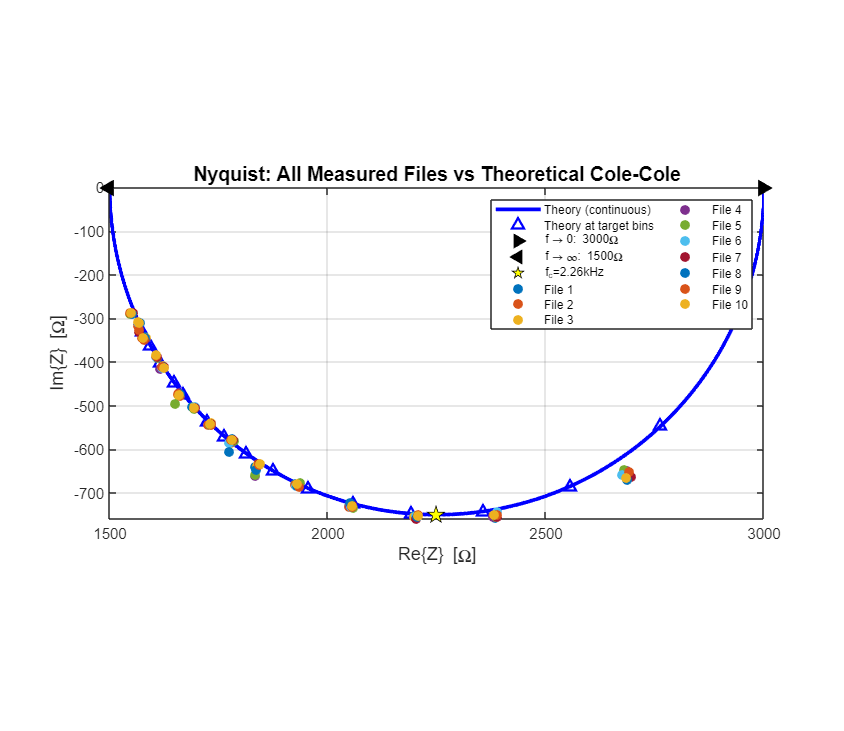

%% ========================================================================
% ĐỒ THỊ NYQUIST – TẤT CẢ FILE TRÊN CÙNG 1 FIGURE
% ========================================================================
figure('Name','Nyquist: Theory vs All Measured Files','Color','w','Position',[100 80 750 650]);
hold on; grid on; box on;

% Đường lý thuyết
plot(real(Z_cont), imag(Z_cont), 'b-', 'LineWidth', 2.5, 'DisplayName', 'Theory (continuous)');
plot(Re_th, Im_th, 'b^', 'MarkerSize', 7, 'MarkerFaceColor','none', ...
    'LineWidth', 1.5, 'DisplayName', 'Theory at target bins');

% Điểm mốc tần số giới hạn
plot(Rs_theory + Rp_theory, 0, 'k>', 'MarkerSize', 9, 'MarkerFaceColor','k', ...
    'DisplayName', sprintf('f\\rightarrow0: %.0f\\Omega', Rs_theory+Rp_theory));
plot(Rs_theory, 0, 'k<', 'MarkerSize', 9, 'MarkerFaceColor','k', ...
    'DisplayName', sprintf('f\\rightarrow\\infty: %.0f\\Omega', Rs_theory));

% Điểm tần số cắt
Z_at_fc = Rs_theory + Rp_theory/(1 + 1j*2*pi*f_c*Rp_theory*Cp_theory);
plot(real(Z_at_fc), imag(Z_at_fc), 'kp', 'MarkerSize', 12, 'MarkerFaceColor','y', ...
    'DisplayName', sprintf('f_c=%.2fkHz', f_c/1e3));

% Vẽ từng file đo
for file_idx = 1:NUM_FILES
    if all(all_Mag_meas(file_idx,:) == 0), continue; end
    plot(all_Re_meas(file_idx,:), all_Im_meas(file_idx,:), 'o', ...
        'MarkerSize', 6, 'Color', colors(file_idx,:), ...
        'MarkerFaceColor', colors(file_idx,:), ...
        'DisplayName', sprintf('File %d', file_idx));
end

axis equal; axis tight;
xlabel('Re\{Z\} [\Omega]', 'FontSize', 12);
ylabel('Im\{Z\} [\Omega]', 'FontSize', 12);
title('Nyquist: All Measured Files vs Theoretical Cole-Cole', 'FontSize', 13);
legend('Location','northeast', 'FontSize', 8, 'NumColumns', 2);

# *Bode plot (Magnitude & phase)*

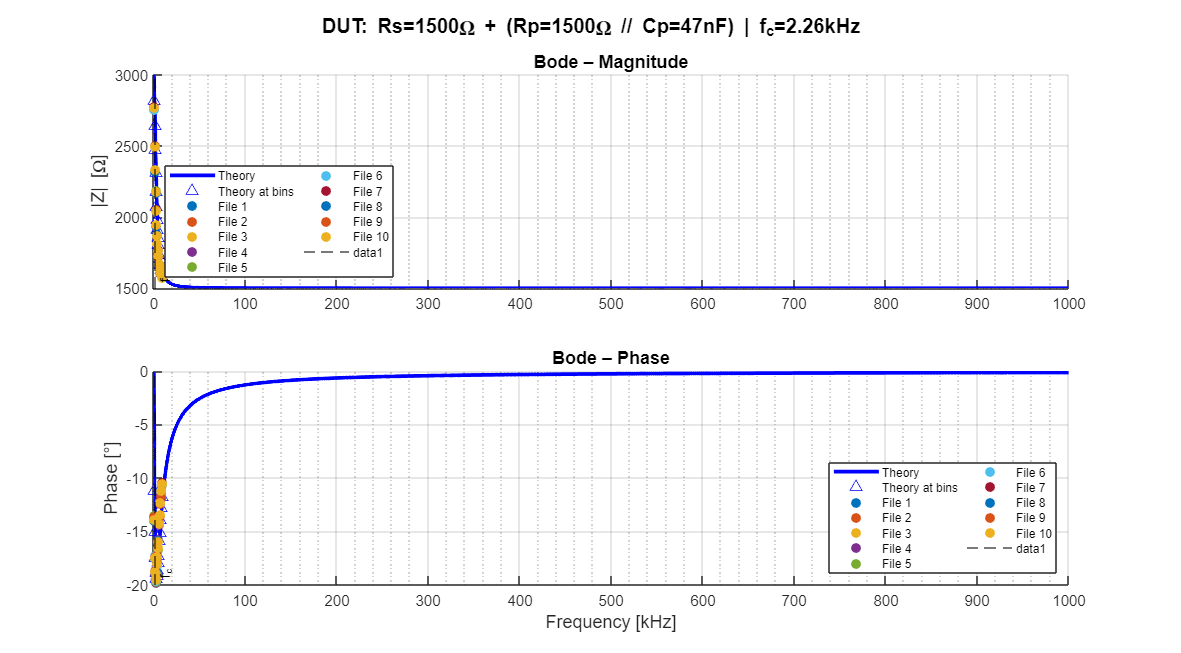

%% ========================================================================
% ĐỒ THỊ BODE – MAGNITUDE & PHASE (TẤT CẢ FILE)
% ========================================================================
figure('Name','Bode: Theory vs All Files','Color','w','Position',[100 100 1050 580]);

subplot(2,1,1); hold on; grid on; set(gca,'XMinorGrid','on');
semilogx(f_cont/1e3, abs(Z_cont), 'b-', 'LineWidth', 2.5, 'DisplayName', 'Theory');
semilogx(f_target/1e3, Mag_th, 'b^', 'MarkerSize', 7, 'DisplayName', 'Theory at bins');
for file_idx = 1:NUM_FILES
    if all(all_Mag_meas(file_idx,:) == 0), continue; end
    semilogx(f_target/1e3, all_Mag_meas(file_idx,:), 'o', ...
        'MarkerSize', 6, 'Color', colors(file_idx,:), ...
        'MarkerFaceColor', colors(file_idx,:), ...
        'DisplayName', sprintf('File %d', file_idx));
end
xline(f_c/1e3,'k--','f_c','LabelVerticalAlignment','bottom','FontSize',9);
ylabel('|Z| [\Omega]', 'FontSize', 12);
title('Bode – Magnitude', 'FontSize', 12);
legend('Location','southwest','FontSize',8,'NumColumns',2);

subplot(2,1,2); hold on; grid on; set(gca,'XMinorGrid','on');
semilogx(f_cont/1e3, angle(Z_cont)*180/pi, 'b-', 'LineWidth', 2.5, 'DisplayName', 'Theory');
semilogx(f_target/1e3, Ph_th, 'b^', 'MarkerSize', 7, 'DisplayName', 'Theory at bins');
for file_idx = 1:NUM_FILES
    if all(all_Ph_meas(file_idx,:) == 0), continue; end
    semilogx(f_target/1e3, all_Ph_meas(file_idx,:), 'o', ...
        'MarkerSize', 6, 'Color', colors(file_idx,:), ...
        'MarkerFaceColor', colors(file_idx,:), ...
        'DisplayName', sprintf('File %d', file_idx));
end
xline(f_c/1e3,'k--','f_c','LabelVerticalAlignment','bottom','FontSize',9);
xlabel('Frequency [kHz]', 'FontSize', 12);
ylabel('Phase [°]', 'FontSize', 12);
title('Bode – Phase', 'FontSize', 12);
legend('Location','southeast','FontSize',8,'NumColumns',2);

sgtitle(sprintf('DUT: Rs=%.0f\\Omega + (Rp=%.0f\\Omega // Cp=%.0fnF) | f_c=%.2fkHz', ...
    Rs_theory, Rp_theory, Cp_theory*1e9, f_c/1e3), 'FontSize', 13, 'FontWeight','bold');

# **Error (Mean only)**

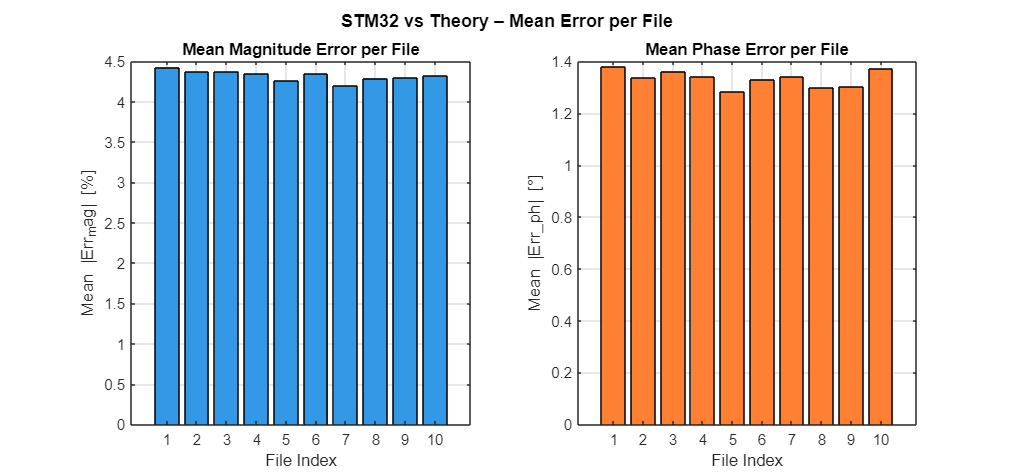

%% ========================================================================
% ĐỒ THỊ SAI SỐ – TỔNG HỢP TẤT CẢ FILE
% ========================================================================
% Tính trung bình sai số theo từng file
mean_err_mag = zeros(1, NUM_FILES);
mean_err_ph  = zeros(1, NUM_FILES);
valid_files  = false(1, NUM_FILES);

for file_idx = 1:NUM_FILES
    if all(all_Mag_meas(file_idx,:) == 0), continue; end
    valid_files(file_idx) = true;
    err_mag = (all_Mag_meas(file_idx,:) - Mag_th) ./ Mag_th * 100;
    err_ph  = all_Ph_meas(file_idx,:) - Ph_th;
    mean_err_mag(file_idx) = mean(abs(err_mag));
    mean_err_ph(file_idx)  = mean(abs(err_ph));
end

figure('Name','Mean Error per File','Color','w','Position',[100 100 900 420]);

subplot(1,2,1);
bar(find(valid_files), mean_err_mag(valid_files), 'FaceColor',[0.2 0.6 0.9]);
xlabel('File Index'); ylabel('Mean |Err_mag| [%]');
title('Mean Magnitude Error per File');
set(gca,'XTick',1:NUM_FILES); grid on;

subplot(1,2,2);
bar(find(valid_files), mean_err_ph(valid_files), 'FaceColor',[1 0.5 0.2]);
xlabel('File Index'); ylabel('Mean |Err\_ph| [°]');
title('Mean Phase Error per File');
set(gca,'XTick',1:NUM_FILES); grid on;

sgtitle('STM32 vs Theory – Mean Error per File', 'FontSize',12,'FontWeight','bold');

# **Hitmap error (file vs frequencies)**

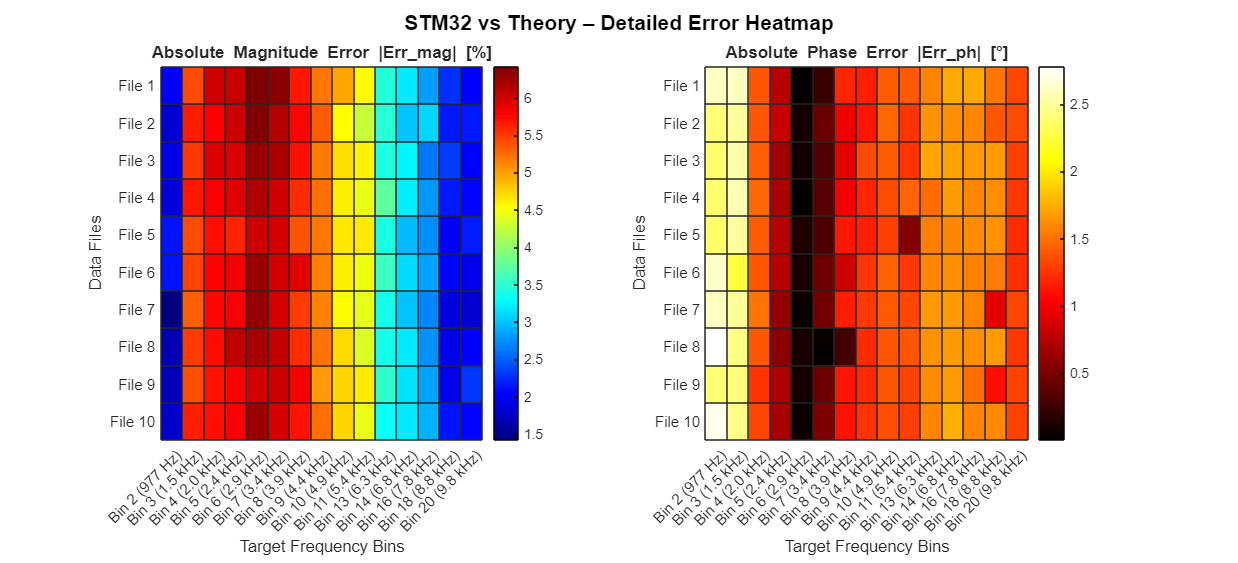

%% ========================================================================
% ĐỒ THỊ SAI SỐ NÂNG CAO – HEATMAP (FILE INDEX vs BIN FREQUENCY)
% ========================================================================
% Tính toán ma trận sai số chi tiết (Kích thước: NUM_FILES x NUM_BINS)
matrix_err_mag = zeros(NUM_FILES, length(bins_noDC));
matrix_err_ph  = zeros(NUM_FILES, length(bins_noDC));

for file_idx = 1:NUM_FILES
    if all(all_Mag_meas(file_idx,:) == 0), continue; end
    matrix_err_mag(file_idx, :) = abs((all_Mag_meas(file_idx,:) - Mag_th) ./ Mag_th * 100);
    matrix_err_ph(file_idx, :)  = abs(all_Ph_meas(file_idx,:) - Ph_th);
end

% Tạo nhãn trục X hiển thị cả số Bin và Tần số tương ứng cho dễ nhìn
x_labels = cell(1, length(bins_noDC));
for k = 1:length(bins_noDC)
    if f_target(k) >= 1000
        x_labels{k} = sprintf('Bin %d\n(%.1f kHz)', bins_noDC(k), f_target(k)/1000);
    else
        x_labels{k} = sprintf('Bin %d\n(%.0f Hz)', bins_noDC(k), f_target(k));
    end
end
y_labels = cellstr(num2str((1:NUM_FILES)', 'File %d'));

% Vẽ đồ thị Heatmap
figure('Name','Advanced Error Analysis - Heatmap','Color','w','Position',[50 50 1100 500]);

% --- Heatmap cho Biên độ ---
subplot(1,2,1);
h1 = heatmap(x_labels, y_labels, matrix_err_mag, 'Colormap', jet, 'ColorbarVisible', 'on');
h1.Title = 'Absolute Magnitude Error |Err\_mag| [%]';
h1.XLabel = 'Target Frequency Bins';
h1.YLabel = 'Data Files';

% --- Heatmap cho Pha ---
subplot(1,2,2);
h2 = heatmap(x_labels, y_labels, matrix_err_ph, 'Colormap', hot, 'ColorbarVisible', 'on');
h2.Title = 'Absolute Phase Error |Err\_ph| [°]';
h2.XLabel = 'Target Frequency Bins';
h2.YLabel = 'Data Files';

sgtitle('STM32 vs Theory – Detailed Error Heatmap', 'FontSize',14,'FontWeight','bold');

# **Error Distibution for each frequency components**

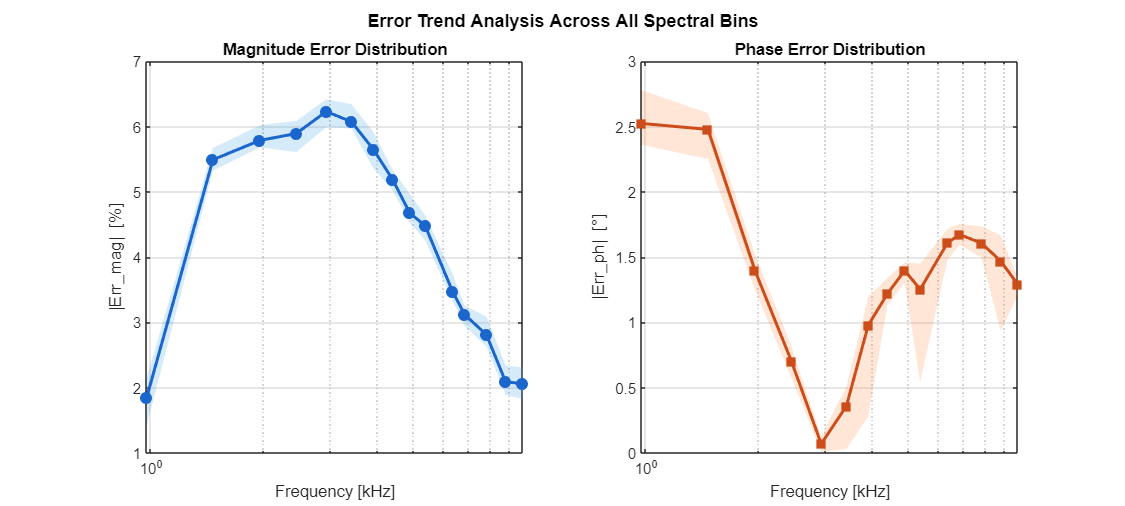

%% ========================================================================
% ĐỒ THỊ SAI SỐ NÂNG CAO – SHADED ERROR BAR THEO TẦN SỐ
% ========================================================================
% Lọc bỏ các file lỗi nếu có
valid_idx = find(any(all_Mag_meas ~= 0, 2));
sub_err_mag = matrix_err_mag(valid_idx, :);
sub_err_ph  = matrix_err_ph(valid_idx, :);

% Tính thống kê theo từng Bin (từng cột)
mean_mag_bin = mean(sub_err_mag, 1);
min_mag_bin  = min(sub_err_mag, [], 1);
max_mag_bin  = max(sub_err_mag, [], 1);

mean_ph_bin  = mean(sub_err_ph, 1);
min_ph_bin   = min(sub_err_ph, [], 1);
max_ph_bin   = max(sub_err_ph, [], 1);

figure('Name','Error Trend Analysis','Color','w','Position',[100 100 1000 450]);

% --- Xu hướng sai số Biên độ ---
subplot(1,2,1);
hold on;
% Vẽ vùng sai số Min-Max (Bóng mờ)
fill([f_target/1000, fliplr(f_target/1000)], [min_mag_bin, fliplr(max_mag_bin)], ...
     [0.2 0.6 0.9], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
% Vẽ đường trung bình
plot(f_target/1000, mean_mag_bin, '-o', 'Color', [0.1 0.4 0.8], 'LineWidth', 2, 'MarkerFaceColor', [0.1 0.4 0.8]);
set(gca, 'XScale', 'log'); % Thường EIS nhìn dạng log tần số sẽ trực quan hơn
grid on; box on;
xlabel('Frequency [kHz]'); ylabel('|Err\_mag| [%]');
title('Magnitude Error Distribution');

% --- Xu hướng sai số Pha ---
subplot(1,2,2);
hold on;
% Vẽ vùng sai số Min-Max (Bóng mờ)
fill([f_target/1000, fliplr(f_target/1000)], [min_ph_bin, fliplr(max_ph_bin)], ...
     [1 0.5 0.2], 'FaceAlpha', 0.2, 'EdgeColor', 'none');
% Vẽ đường trung bình
plot(f_target/1000, mean_ph_bin, '-s', 'Color', [0.8 0.3 0.1], 'LineWidth', 2, 'MarkerFaceColor', [0.8 0.3 0.1]);
set(gca, 'XScale', 'log');
grid on; box on;
xlabel('Frequency [kHz]'); ylabel('|Err\_ph| [°]');
title('Phase Error Distribution');

sgtitle('Error Trend Analysis Across All Spectral Bins', 'FontSize',12,'FontWeight','bold');